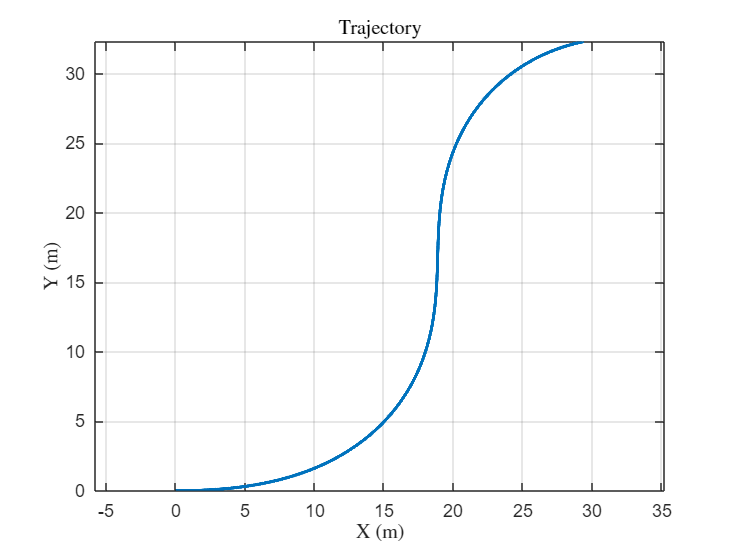

%  Aidan Fitzpatrick - ROB-GY 7863 AMR Project
%  4-Wheeled Anti-Ackermann (RWD) Car

%  PD Feedback Linearization Control (PD-FLC) on yaw (theta)
%  State: x = [X;Y;theta;Vx;Vy;omega]

clc;
clear all;
close all;

% Parameters (P)
P.m   = 700;         
P.Izz = 800;         
P.l   = 3.6/2;
P.b   = 2.0/2;       

P.k_lat = 80000; %lateral stiffness   

P.Fmax = 8000; %max force
P.Fmin = -8000;% min force

%for steering profile
P.steerA = deg2rad(15);
P.steerW = 0.5;
P.steerK = 1.2;

% for desired motion
P.Vx_ref = 8.0;
P.thetaA = deg2rad(35);
P.thetaW = 0.25;

% Control Gains
P.Kv = 2.5;
P.Kp = 12.0;
P.Kd = 8.0;




%initial state
x0 = [0; 0; 0; 5; 0; 0];


tspan = [0 10];

% **
opts = odeset('RelTol',1e-6,'AbsTol',1e-8);
[t, X] = ode45(@(t,x) dynamics_PD_FLC_yaw(t,x,P), tspan, x0, opts);

Xpos  = X(:,1);
Ypos  = X(:,2);
theta = X(:,3);
Vx    = X(:,4);
Vy    = X(:,5);
omega = X(:,6);









N = numel(t);
theta_d = zeros(N,1);
theta_d_dot = zeros(N,1);
theta_d_ddot = zeros(N,1);
Vx_d = P.Vx_ref * ones(N,1);
F3 = zeros(N,1);
F4 = zeros(N,1);






for k = 1:N
    [theta_d(k), theta_d_dot(k), theta_d_ddot(k)] = theta_ref(t(k),P);
    [F3(k), F4(k)] = control_FLC(t(k), X(k,:).', P);
end

%Errors
e_theta     = theta - theta_d;
e_theta_dot = omega - theta_d_dot;
e_Vx        = Vx - Vx_d;





figure;
plot(Xpos,Ypos,'LineWidth',2);
axis equal; grid on;
xlabel('X (m)','Interpreter','latex');
ylabel('Y (m)','Interpreter','latex');
title('Trajectory','Interpreter','latex');

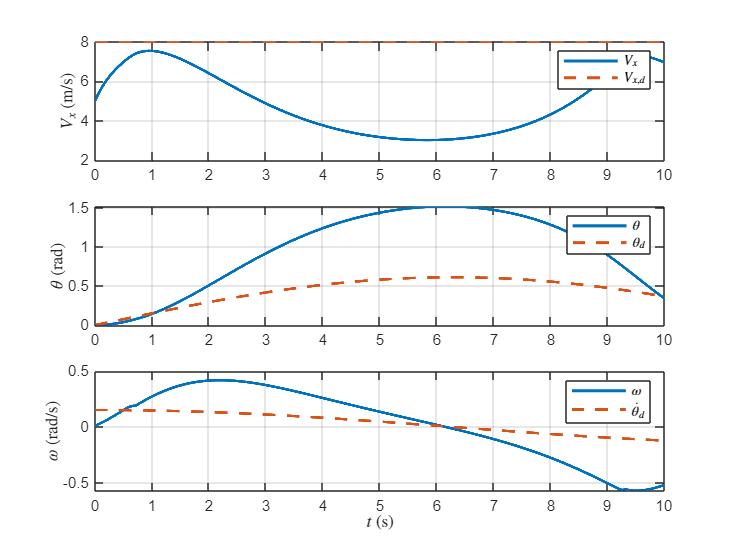


% Tracking
figure;
subplot(3,1,1);
plot(t,Vx,'LineWidth',1.7); hold on;
plot(t,Vx_d,'--','LineWidth',1.7);
ylabel('$V_x$ (m/s)','Interpreter','latex');
legend('$V_x$','$V_{x,d}$','Interpreter','latex');
grid on;

subplot(3,1,2);
plot(t,theta,'LineWidth',1.7); hold on;
plot(t,theta_d,'--','LineWidth',1.7);
ylabel('$\theta$ (rad)','Interpreter','latex');
legend('$\theta$','$\theta_d$','Interpreter','latex');
grid on;

subplot(3,1,3);
plot(t,omega,'LineWidth',1.7); hold on;
plot(t,theta_d_dot,'--','LineWidth',1.7);
ylabel('$\omega$ (rad/s)','Interpreter','latex');
xlabel('$t$ (s)','Interpreter','latex');
legend('$\omega$','$\dot{\theta}_d$','Interpreter','latex');
grid on;

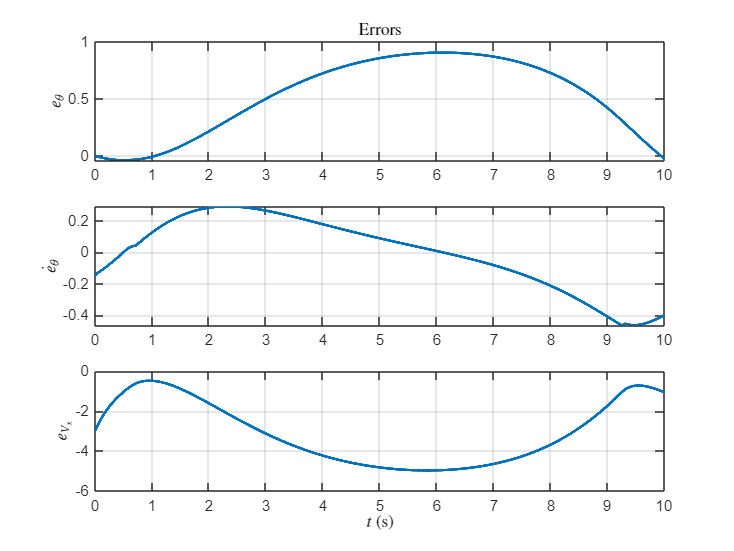


figure;
subplot(3,1,1);
plot(t,e_theta,'LineWidth',1.7);
ylabel('$e_\theta$','Interpreter','latex');
title('Errors','Interpreter','latex');
grid on;

subplot(3,1,2);
plot(t,e_theta_dot,'LineWidth',1.7);
ylabel('$\dot e_\theta$','Interpreter','latex');
grid on;

subplot(3,1,3);
plot(t,e_Vx,'LineWidth',1.7);
ylabel('$e_{V_x}$','Interpreter','latex');
xlabel('$t$ (s)','Interpreter','latex');
grid on;

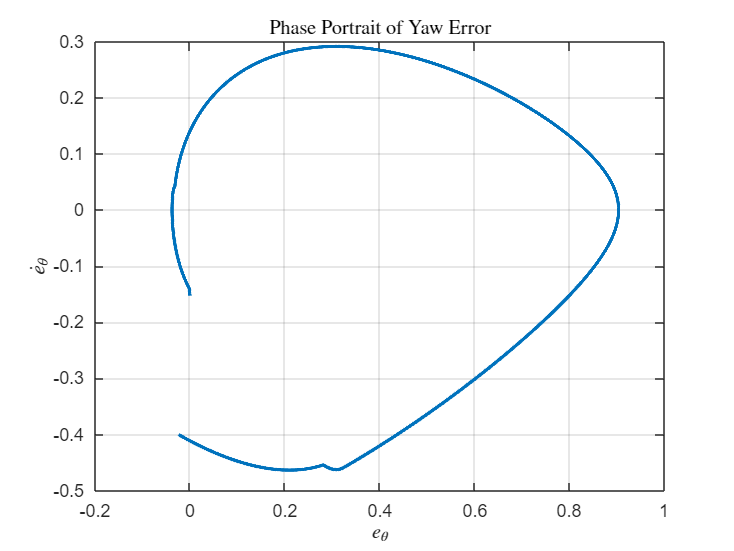


figure;
plot(e_theta,e_theta_dot,'LineWidth',2);
xlabel('$e_\theta$','Interpreter','latex');
ylabel('$\dot e_\theta$','Interpreter','latex');
title('Phase Portrait of Yaw Error','Interpreter','latex');
grid on;

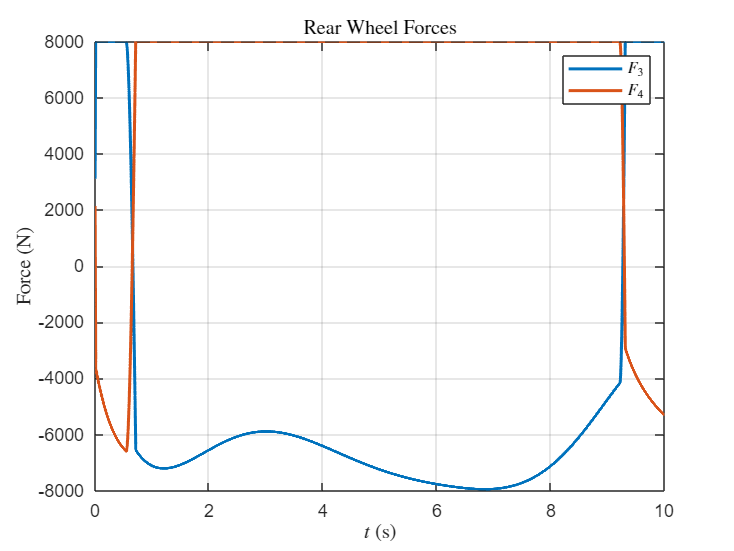


figure;
plot(t,F3,'LineWidth',1.7); hold on;
plot(t,F4,'LineWidth',1.7);
yline(P.Fmax,'--'); yline(P.Fmin,'--');
xlabel('$t$ (s)','Interpreter','latex');
ylabel('Force (N)','Interpreter','latex');
legend('$F_3$','$F_4$','Interpreter','latex');
title('Rear Wheel Forces','Interpreter','latex');
grid on;








% Dynamics
function dx = dynamics_PD_FLC_yaw(t,x,P)
    th = x(3); Vx = x(4); Vy = x(5); om = x(6);

    [d1,d2] = steering_profile(t,P);
    deltas = [d1; d2; 0; 0];

    xw = [ P.l; P.l; -P.l; -P.l ]; %position of wheels (x,y)
    yw = [-P.b; P.b; -P.b; P.b ];

    v_lat = zeros(4,1);
    for i=1:4
        vx_i = Vx - om*yw(i);
        vy_i = Vy + om*xw(i);
        v_lat(i) = -vx_i*sin(deltas(i)) + vy_i*cos(deltas(i));
    end
    Flat = -P.k_lat * v_lat;

    [F3,F4] = control_FLC(t,x,P);
    Flong = [0;0;F3;F4];

    Fx = Flong.*cos(deltas) - Flat.*sin(deltas);
    Fy = Flong.*sin(deltas) + Flat.*cos(deltas);

    tau = xw.*Fy - yw.*Fx;

    Vx_dot = sum(Fx)/P.m + om*Vy;
    Vy_dot = sum(Fy)/P.m - om*Vx;
    om_dot = sum(tau)/P.Izz;

    X_dot = Vx*cos(th) - Vy*sin(th);
    Y_dot = Vx*sin(th) + Vy*cos(th);
    th_dot = om;

    dx = [X_dot; Y_dot; th_dot; Vx_dot; Vy_dot; om_dot];
end

% Control Law PD-FLC
function [F3,F4] = control_FLC(t,x,P)
    th = x(3); Vx = x(4); Vy = x(5); om = x(6);

    [d1,d2] = steering_profile(t,P);
    deltas = [d1; d2; 0; 0];

    xw = [ P.l; P.l; -P.l; -P.l ];
    yw = [-P.b; P.b; -P.b; P.b ];

    v_lat = zeros(4,1);


    for i=1:4
        vx_i = Vx - om*yw(i);
        vy_i = Vy + om*xw(i);
        v_lat(i) = -vx_i*sin(deltas(i)) + vy_i*cos(deltas(i));
    end
    
    Flat = -P.k_lat * v_lat;

    Fx0 = -Flat.*sin(deltas);
    Fy0 =  Flat.*cos(deltas);
    tau0 = xw.*Fy0 - yw.*Fx0;

    Vx_dot0 = sum(Fx0)/P.m + om*Vy;
    om_dot0 = sum(tau0)/P.Izz;

    [th_d, th_d_dot, th_d_ddot] = theta_ref(t,P);

    Vx_dot_cmd = -P.Kv*(Vx - P.Vx_ref);
    Fsum = P.m*(Vx_dot_cmd - Vx_dot0);

    e_th  = th - th_d;
    e_thd = om - th_d_dot;

    th_ddot_cmd = th_d_ddot - P.Kd*e_thd - P.Kp*e_th;
    Fdiff = (P.Izz/P.b)*(th_ddot_cmd - om_dot0);

    F3 = 0.5*(Fsum + Fdiff);
    F4 = 0.5*(Fsum - Fdiff);

    F3 = min(max(F3,P.Fmin),P.Fmax);
    F4 = min(max(F4,P.Fmin),P.Fmax);
end


% Same steering as main loop
function [d1,d2] = steering_profile(t,P)
    base = P.steerA*sin(P.steerW*t);
    if base>=0
        d2 = base;
        d1 = P.steerK*base;
    else
        d1 = base;
        d2 = P.steerK*base;
    end
end

% Desired Heading
function [th_d,th_d_dot,th_d_ddot] = theta_ref(t,P)
    th_d = P.thetaA*sin(P.thetaW*t);
    th_d_dot = P.thetaA*P.thetaW*cos(P.thetaW*t);
    th_d_ddot = -P.thetaA*(P.thetaW^2)*sin(P.thetaW*t);
end
